# Expand Example 2.12:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RC circuit shown below. The switch is moved from position A to position B at time $t=t_{0}$ instead of at $t=0$.

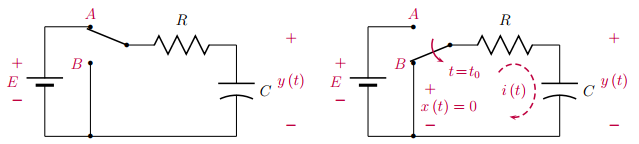

The homogeneous differential equation is in the form

        
$$\frac{dy}{dt}+\frac{1}{RC}\,y(t)=0$$


The homogeneous solution is

        
$$y_{h}(t) = c\,e^{-t/RC}$$


It must satisfy the initial condition $y_{h}(t_{0})=E$, therefore

          
$$c=E\,e^{t_{0}/RC}$$


R = 1; % Resistance
C = 0.25; % Capacitance

t0 = -0.5; % Time instant for moving the switch
E  = 10;  % Battery voltage

Compute and graph the natural response:

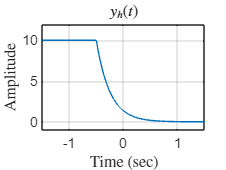

alpha = 1/(R*C);
c = E*exp(alpha*t0);
t = [t0-1:0.005:t0+2];
yh = E*(t<t0)+c*exp(-alpha*t).*(t>=t0);
plot(t,yh); grid;
axis([t0-1,t0+2,-1,12]);
set(0,'defaultTextInterpreter','latex');
xlabel('Time (sec)');
ylabel('Amplitude');
title('$y_{h}(t)$');

set(0,'defaultTextInterpreter','tex');